Mp=0.05;
ts=0.5;

zheta=sqrt(((log(Mp))^2)/(pi^2+(log(Mp))^2))

zheta = 0.6901

wn=4/(zheta*ts)

wn = 11.5924

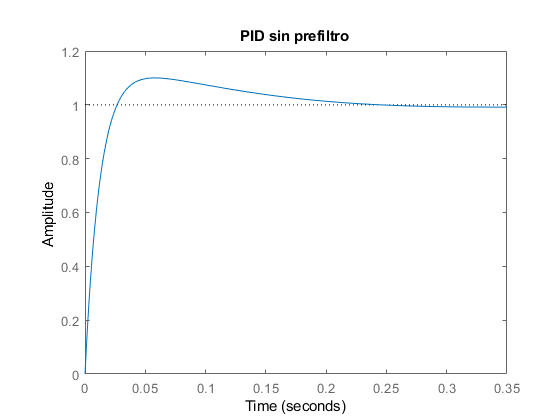


B=1/((s^2+zheta*2*wn*s+wn^2)*(s+800));

FunM1= tf([4.121],[0.2475,1]);
PID=84.925322423+645.4007231/s+5.522722204*s;
Lc=feedback(PID*FunM1/s,1);

stepplot(Lc)
title('PID sin prefiltro')

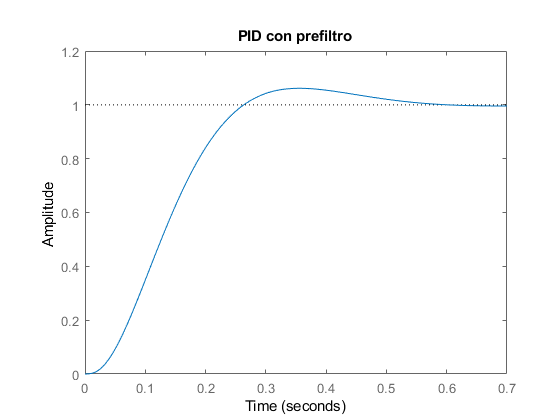


prefiltro1=1/(200.9*s^2 + 3201*s + 2.66e04);

stepplot(prefiltro1*Lc/dcgain(prefiltro1))
title('PID con prefiltro')